% clear 
% 
% realId = 1;
% im = imread("../Faces/db1_" + realId + ".jpg");

Error using imread>get_full_filename
File "../Faces/db1_1.jpg" does not exist.

Error in imread (line 372)
        fullname = get_full_filename(filename);

% imshow(im)
% 
% % Gray world comp start
% imR = im(:,:,1);
% imG = im(:,:,2);
% imB = im(:,:,3);
% 
% [m,n,~] = size(im);
% R_avg = 1/(m*n)*sum(sum(imR)) 
% G_avg = 1/(m*n)*sum(sum(imG)) 
% B_avg = 1/(m*n)*sum(sum(imB))
% 
% minAvgDiff = 6;
% 
% % Kan bli problematiskt med mycket färger i bakgrunden
% if abs(R_avg - G_avg) > minAvgDiff || abs(R_avg - B_avg) > minAvgDiff || abs(B_avg - G_avg) > minAvgDiff
%     alpha = G_avg / R_avg;
%     beta = G_avg / B_avg;
% 
%     im(:,:,1) = alpha * imR;
%     im(:,:,3) = beta  * imB;
% end    
% imshow(im)
% % Gray world comp end

% % Fylla hål för mask start
% im = imread("badMask.png");
% im = im(:,:,1);
% imshow(im)

% im = imfill(im, 'holes');
% imshow(im)
% % Fylla hål för mask end

% % Color-based method start
% realId = 1;
% im = imread("../Faces/db1_" + realId + ".jpg");
% 
% im = sum(im,3)./(3*255);
% im = ( im - min(min(im)) )/( max(max(im)) - min(min(im)) );
% im = im > 0.5;
% 
% % Create a Gaussian filter kernel
% sigma = 2;
% filter_size = 2 * ceil(3 * sigma) + 1;  % Determine the filter size
% gaussian_filter = fspecial('gaussian', filter_size, sigma);
% 
% % Apply the Gaussian filter to the image
% im = imfilter(double(im), gaussian_filter, 'conv', 'replicate');
% 
% r = 12;
% SE = strel('disk',r);
% im2 = ~imopen(im, SE);% behåller bara det som INTE passar i SE
% imshow(im2)
% im = im .* im2;
% imshow(im)
% % Color-based method end
% 
% 

% realId = 1;
% im = imread("../Faces/db1_" + realId + ".jpg");
% imGray = rgb2gray(im);
% 
% % Define the Sobel kernels for horizontal and vertical edge detection
% sobelY = [-1, 0, 1; -2, 0, 2; -1, 0, 1];% Horizontal
% sobelX = [-1, -2, -1; 0, 0, 0; 1, 2, 1];% Vertical
% 
% % Perform convolution with Sobel kernels to detect edges
% edgesY = conv2(double(imGray), sobelY, 'same');
% edgesX = conv2(double(imGray), sobelX, 'same');
% 
% % Calculate the magnitude of the edges
% imSobel = sqrt(edgesY.^2 + edgesX.^2);
% 
% % Adjust the edge magnitude to the range [0, 255]
% imSobel = uint8(255 * (imSobel / max(imSobel(:))));
% 
% imshow(imSobel)
% 
% r = 12;
% SE = strel('disk',r);
% im2 = ~imopen(im, SE);% behåller bara det som INTE passar i SE

% % Load the RGB image
% realId = 1;
% im = imread("rapportbild.png");
% 
% imR = im(:,:,1);
% imG = im(:,:,2);
% imB = im(:,:,3);
% 
% [m,n,~] = size(im);
% R_avg = 1/(m*n)*sum(sum(imR)) 

R_avg = 176.6191

% G_avg = 1/(m*n)*sum(sum(imG)) 

G_avg = 158.4757

% B_avg = 1/(m*n)*sum(sum(imB))

B_avg = 137.1027

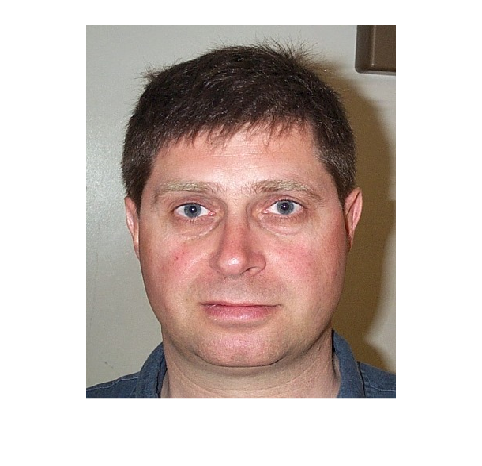

% 
% minAvgDiff = 6;
% 
% % Kan bli problematiskt med mycket färger i bakgrunden
% if abs(R_avg - G_avg) > minAvgDiff || abs(R_avg - B_avg) > minAvgDiff || abs(B_avg - G_avg) > minAvgDiff
%     alpha = G_avg / R_avg;
%     beta = G_avg / B_avg;
% 
%     im(:,:,1) = alpha * imR;
%     im(:,:,3) = beta  * imB;
% end    
% rgb_image = im;
% 
% % Convert the RGB image to the YCbCr color space
% ycbcr_image = rgb2ycbcr(rgb_image);
% 
% % Extract the Y, Cb, and Cr components
% Y = im2double(ycbcr_image(:, :, 1));
% Cb = im2double(ycbcr_image(:, :, 2));
% Cr = im2double(ycbcr_image(:, :, 3));
% 
% % Display or process the Y, Cb, and Cr components as needed
% imshow(ycbcr_image)

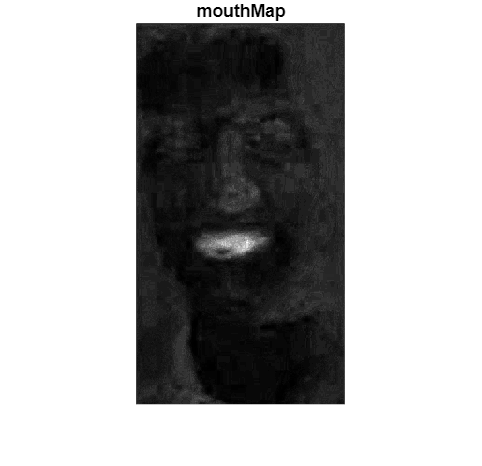

% 
% % EyeMapC
% %eyeMapC = 1/3 * (Cb.^2 + (1 - Cr).^2 + Cb./Cr);
% %eyeMapC = eyeMapC./max(max(eyeMapC));
% 
% %imshow(eyeMapC); title('eyeMapC')
% 
% % EyeMapL
% SE = strel('disk', 8);  % Adjust the size as needed
% 
% % Perform dilation on the binary image
% %eyeMapL = double(imdilate(Y, SE)./(imerode(Y, SE)+1));
% %eyeMapL = eyeMapL./max(max(eyeMapL));
% %imshow(eyeMapL); title('eyeMapL')
% 
% % EyeMap
% %eyeMap = (eyeMapL .* eyeMapC);
% %imshow(eyeMap); title('eyeMap')
% 
% % mouthMap
% n = 0.95 * mean(mean(Cr.^2)) / mean(mean(Cr./Cb));
% mouthMap = Cr.^2 .* (Cr.^2 - n.*Cr./Cb).^2;
% mouthMap = mouthMap./max(max(mouthMap));
% imshow(mouthMap); title('mouthMap')

% im = im2double(imread("../Faces/db1_" + 1 + ".jpg"));
% 
% map = dilationDisk(eyeMap(AWB(im,6)),10);

'AWB' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\Wille\Documents\GitHub\TNM034_Projekt

Change the MATLAB current folder or add its folder to the MATLAB path.

% map = map > 0.9;
% imshow(map)
% 
% 
% 

# Sansbox

## AWB

% clear 
% 
% realId = 1;
% im = imread("../Faces/db1_" + realId + ".jpg");
% %imshow(im)
% 
% % Gray world comp start
% imR = im(:,:,1);
% imG = im(:,:,2);
% imB = im(:,:,3);
% 
% [m,n,~] = size(im);
% R_avg = 1/(m*n)*sum(sum(imR)) 
% G_avg = 1/(m*n)*sum(sum(imG)) 
% B_avg = 1/(m*n)*sum(sum(imB))
% 
% minAvgDiff = 6;
% 
% % Kan bli problematiskt med mycket färger i bakgrunden
% if abs(R_avg - G_avg) > minAvgDiff || abs(R_avg - B_avg) > minAvgDiff || abs(B_avg - G_avg) > minAvgDiff
%     alpha = G_avg / R_avg;
%     beta = G_avg / B_avg;
% 
%     im(:,:,1) = alpha * imR;
%     im(:,:,3) = beta  * imB;
% end    
% %imshow(im)
% % Gray world comp end

## Test hole filling

% % Fylla hål för mask start
% im = imread("badMask.png");
% im = im(:,:,1);
% imshow(im)
% im = imfill(im, 'holes');
% imshow(im)
% % Fylla hål för mask end

## Old Color-based method

% 
% % Color-based method start
% realId = 1;
% im = imread("../Faces/db1_" + realId + ".jpg");
% 
% im = sum(im,3)./(3*255);
% im = ( im - min(min(im)) )/( max(max(im)) - min(min(im)) );
% im = im > 0.5;
% 
% % Create a Gaussian filter kernel
% sigma = 2;
% filter_size = 2 * ceil(3 * sigma) + 1;  % Determine the filter size
% gaussian_filter = fspecial('gaussian', filter_size, sigma);
% 
% % Apply the Gaussian filter to the image
% im = imfilter(double(im), gaussian_filter, 'conv', 'replicate');
% 
% r = 12;
% SE = strel('disk',r);
% im2 = ~imopen(im, SE);% behåller bara det som INTE passar i SE
% imshow(im2)
% im = im .* im2;
% imshow(im)
% % Color-based method end


## Realy old playground

% % Load the RGB image
% realId = 1;
% im = imread("rapportbild.png");
% 
% imR = im(:,:,1);
% imG = im(:,:,2);
% imB = im(:,:,3);
% 
% [m,n,~] = size(im);
% R_avg = 1/(m*n)*sum(sum(imR)) 
% G_avg = 1/(m*n)*sum(sum(imG)) 
% B_avg = 1/(m*n)*sum(sum(imB))
% 
% minAvgDiff = 6;
% 
% % Kan bli problematiskt med mycket färger i bakgrunden
% if abs(R_avg - G_avg) > minAvgDiff || abs(R_avg - B_avg) > minAvgDiff || abs(B_avg - G_avg) > minAvgDiff
%     alpha = G_avg / R_avg;
%     beta = G_avg / B_avg;
% 
%     im(:,:,1) = alpha * imR;
%     im(:,:,3) = beta  * imB;
% end    
% rgb_image = im;
% 
% % Convert the RGB image to the YCbCr color space
% ycbcr_image = rgb2ycbcr(rgb_image);
% 
% % Extract the Y, Cb, and Cr components
% Y = im2double(ycbcr_image(:, :, 1));
% Cb = im2double(ycbcr_image(:, :, 2));
% Cr = im2double(ycbcr_image(:, :, 3));
% 
% % Display or process the Y, Cb, and Cr components as needed
% imshow(ycbcr_image)
% 
% % EyeMapC
% %eyeMapC = 1/3 * (Cb.^2 + (1 - Cr).^2 + Cb./Cr);
% %eyeMapC = eyeMapC./max(max(eyeMapC));
% 
% %imshow(eyeMapC); title('eyeMapC')
% 
% % EyeMapL
% SE = strel('disk', 8);  % Adjust the size as needed
% 
% % Perform dilation on the binary image
% %eyeMapL = double(imdilate(Y, SE)./(imerode(Y, SE)+1));
% %eyeMapL = eyeMapL./max(max(eyeMapL));
% %imshow(eyeMapL); title('eyeMapL')
% 
% % EyeMap
% %eyeMap = (eyeMapL .* eyeMapC);
% %imshow(eyeMap); title('eyeMap')

## ycbcr image from RGB

% i = 4;
% im = im2double(imread("Faces/db1_" + i + ".jpg"));
% rgb_image = im;
% 
% % Convert the RGB image to the YCbCr color space
% ycbcr_image = rgb2ycbcr(rgb_image);
% 
% % Extract the Y, Cb, and Cr components
% Y = im2double(ycbcr_image(:, :, 1));
% Cb = im2double(ycbcr_image(:, :, 2));
% Cr = im2double(ycbcr_image(:, :, 3));

## Gamalt mask test

% % mouthMap
% for i = 1:16
%     for j=1:1
%     im = im2double(imread("Faces/db1_" + i + ".jpg"));
% 
%     map = dilationDisk(eyeMap((colorCorrection(im))),6);
%     mask = faceMask1(im);
% 
%     mask = histeq(mask*255);
%     mask = mask/max(max(mask));
%     mask = map.*mask;
%     mask = max(max(mask))*0.8 < mask;
%     imshow(mask); title(i)
%     pause(0.5)
%     end
% end


## Gammalt filter test

% i = 10;
% im = im2double(imread("Faces/db1_" + i + ".jpg"));
% %n = 0.95 * mean(mean(Cr.^2)) / mean(mean(Cr./Cb));
% %mouthMap = Cr.^2 .* (Cr.^2 - n.*Cr./Cb).^2;
% %mouthMap = mouthMap./max(max(mouthMap));
% %imshow(mouthMap); title('mouthMap')
% im = AWB(colorCorrection(im),1);
% map = eyeMap(AWB(im,1));
% 
% imGray = rgb2gray(im);
% imSobel = edge(imGray, 'sobel');
% 
% SE = strel('disk', 4);  
% imgdil1 = imdilate(imSobel, SE);
% imgdil2 = imdilate(imgdil1, SE);
% 
% imger1 = imerode(imgdil2, SE);
% imger2 = imerode(imger1, SE);
% edgeDenImg = imerode(imger2, SE);
% 
% imshow(edgeDenImg)
% 
% mask = faceMask1(im);
% mask = map.*mask;
% mask = max(max(mask))*0.9 < mask;
% mask = bwareafilt(mask, 2);
% 
% imshow(mask); title(i)

## Test edge filter

% i = 5;
% im = im2double(imread("Faces/db1_" + i + ".jpg"));
% im = AWB(colorCorrection(im),1);
% 
% imGray = rgb2gray(im);
% imFSobel = edge(imGray, 'sobel');
% 
% sobX = [-1 -2 -1; 
%          0 0 0; 
%          1 2 1];
% 
% sobY = [-1 0 1;
%         -2 0 2; 
%         -1 0 1];
% 
% imSobelX = imfilter(imGray,sobX);
% imSobelY = imfilter(imGray,sobY);
% 
% imSobel = sqrt(imSobelX.^2 + imSobelY.^2) > 0.5;
% imshow(imFSobel)
% imshow(imSobel)

## Slutgiltig test av sumering av 3 filtermasker

% i = 15;
% im = im2double(imread("Faces/db1_" + i + ".jpg"));
% im = AWB(colorCorrection(im),1);
% mask1 = faceMask1(im);
% %imshow(mask1)
% 
% im = im2double(imread("Faces/db1_" + i + ".jpg"));
% mask2 = faceMask2(im);
% %imshow(mask2); 
% %imshow(im); 
% 
% im = im2double(imread("Faces/db1_" + i + ".jpg"));
% 
% map = dilationDisk(eyeMap((colorCorrection(im))),6);
% mask3 = faceMask3(im);
% %imshow(mask3); 
% 
% maskA = mask1 .* mask2;
% maskC = mask1 .* mask3;
% maskB = mask2 .* mask3;
% 
% mask = maskA | maskB | maskC;
% map = dilationDisk(eyeMap((colorCorrection(im))),6);
% % mask map to only the area where eyes can be
% map = eyesWindow(map);
% 
% filt = map.*mask;
% filtMask = max(max(filt))*0.8 < filt;
% imshow(filtMask)


## Test av ögon fönster

for i=1:16
im = im2uint8(imread("Faces/db1_" + i + ".jpg"));

[n, m, d] = size(im);

im(round((n/2-n*0.18)):round((n/2+n*0.09)), round(m/2-n*0.25):round(m/2+n*0.25),1) = 0;
imshow(im)
pause(0.01)
end

## Mäst utveklad kod på alla bilder

for i=1:16
for j=1:4
    im = im2double(imread("Faces/db1_" + i + ".jpg"));
    im = AWB(colorCorrection(im),1);

    mask1 = faceMask1(im);
    mask2 = faceMask2(im);
    mask3 = faceMask3(im);
    
    % AND == *
    maskA = mask1 .* mask2;
    maskC = mask1 .* mask3;
    maskB = mask2 .* mask3;
    
    % Or == |
    mask = maskA | maskB | maskC;
    
    map = dilationDisk(eyeMap((colorCorrection(im))),6);
    
    % mask map to only the area where eyes can be
    map = eyesWindow(map);
    
    filt = map.*mask;
    filtMask = max(max(filt))*0.7 < filt;
    filtMask = bwareafilt(filtMask, 2);
    filtMask = dilationDisk(filtMask,8);
    
    %imshow(filtMask.*im); title(i)

    % Label the connected components in the binary image
    labeled_image = bwlabel(filtMask);
    
    % Calculate the region properties, including the centroids, of the labeled components
    stats = regionprops(labeled_image, 'Centroid');
    
    % Extract the centroids of the circles
    centroid1 = stats(1).Centroid;
    centroid2 = stats(2).Centroid;
    
    im = drawX(im,centroid1(1),centroid1(2));
    im = drawX(im,centroid2(1),centroid2(2));
    
    imshow(im); title(i)

    pause(0.1)
end
end

# **Mäst utveklad kod**



i = 5;    
im = im2double(imread("Faces/db1_" + i + ".jpg"));
imCorrected = AWB(colorCorrection(im),1);

% Se TNM034_2023_Le2.pdf sida 81
mask1 = faceMask1(imCorrected);
mask2 = faceMask2(imCorrected);
mask3 = faceMask3(imCorrected);

% AND == *
maskA = mask1 .* mask2;
maskC = mask1 .* mask3;
maskB = mask2 .* mask3;

% Or == |
mask = maskA | maskB | maskC;

map = dilationDisk(eyeMap((colorCorrection(im))),6);
imshow(map); title('map')
% mask map to only the area where eyes can be
window = eyesWindow(imCorrected);
map = map .*window;
imshow(window); title('window')

filt = map.*mask;
imshow(filt); title('filt')

filtMask = max(max(filt))*0.7 < filt;
%imshow(filtMask); title('filtMask')
filtMask = bwareafilt(filtMask, 2);% Sparar bara de två största vita fläckarna
filtMask = dilationDisk(filtMask,8);
imshow(filt); title('filtMask')


% Label the connected components in the binary image
labeled_image = bwlabel(filtMask);

% Calculate the region properties, including the centroids, of the labeled components
stats = regionprops(labeled_image, 'Centroid');

% Extract the centroids of the circles
centroid1 = stats(1).Centroid;
centroid2 = stats(2).Centroid;

%imX = drawX(im,centroid1(1),centroid1(2));
%imX = drawX(imX,centroid2(1),centroid2(2));

%imshow(imX); title('Eye position using masking and filtering')
imIn = im;
[eye1,eye2] = findEyesUsingCircularHough(imIn, centroid1, centroid2);

imX = drawX(im,eye1(1),eye1(2));
imX = drawX(imX,eye2(1),eye2(2));

imshow(imX); title('Eye-position using masking and filtering and Hough')

% Gör ett window utifrån centroid1 punkterna så båda ögonen är med men inte
% så mycket mer
% Använd sedan Circular Hough transform för att hitta ögat i bilden
% Sen är normalicering redo

## Circular Hough transform on masked eye maps

imIn = im;


[n, m, ~] = size(imIn);
mask = zeros(n,m);

eye1n = centroid1(1);
eye1m = centroid1(2);
eye2n = centroid2(1);
eye2m = centroid2(2);

mask(round((eye1m-25)):round((eye1m+25)), round(eye1n-25):round(eye1n+25)) = 1;
mask(round((eye2m-25)):round((eye2m+25)), round(eye2n-25):round(eye2n+25)) = 1;


imMask = imIn .* mask;
imMask = imMask + ~mask;
imshow(imMask); title('Mask around centroids')

[centers, radii, ~] = imfindcircles(imMask,[8 200],'ObjectPolarity','dark')
centersStrong2 = centers(1:2,:); 
radiiStrong2 = radii(1:2);
viscircles(centersStrong2, radiiStrong2,'EdgeColor','b');

eye1 = centers(1,:) 
eye2 = centers(2,:)

## Circular Hough transform NOT GOOD


% i = 1;
% im = im2double(imread("Faces/db1_" + i + ".jpg"));
% [n, m, ~] = size(im);
% 
% [centers, radii, metric] = imfindcircles(im,[8 100],'ObjectPolarity','dark');
% 
% centersStrong5 = centers(1:2,:); 
% radiiStrong5 = radii(1:2);
% metricStrong5 = metric(1:2);
% 
% im = drawX(im,centersStrong5(1,1),centersStrong5(1,2));
% im = drawX(im,centersStrong5(2,1),centersStrong5(2,2));
% imshow(im)
% pause(0.1)

j = 5;
    imIn = im2double(imread("Faces/db1_" + j + ".jpg"));
    
    % mun bild ----------------
    
    % Convert the RGB image to the YCbCr color space
    ycbcr_image = rgb2ycbcr(imIn);
    
    % Extract the Y, Cb, and Cr components
    Y = im2double(ycbcr_image(:, :, 1));
    Cb = im2double(ycbcr_image(:, :, 2));
    Cr = im2double(ycbcr_image(:, :, 3));
    
    n = 0.95 * mean(mean(Cr.^2)) / mean(mean(Cr./Cb));
    mouthMap = Cr.^2 .* (Cr.^2 - n.*Cr./Cb).^2;
    mouthMap = mouthMap./max(max(mouthMap));
    mouthMap = dilationDisk(mouthMap,12);
    mouthMap = max(max(mouthMap)).*0.4 < mouthMap; 
    mouthMap = imfill(mouthMap, 'holes');
    mouthMap = bwareafilt(mouthMap, 1);% Sparar bara det största området

    labeled_image = bwlabel(mouthMap);
    stats = regionprops(logical(labeled_image), 'Centroid');
    ce = stats(1).Centroid;

    [n, m, ~] = size(imIn);
    mask = zeros(n,m);
    mask(round((ce(2)-1.1*n/3)):round((ce(2)-n/8)), round(ce(1)-m/4):round(ce(1)+m/4),1) = 1;
    imOut = mask;

    %imX = drawX(imIn,ce(1),ce(2));

    imshow(imOut); title(j)
    pause(0.1)
    % --------------------------
    



    imIn = im2double(imread("Faces/db1_" + 4 + ".jpg"));

imshow(imIn)

% ögon mask --------------
imIn = im2double(imIn);

[n, m, ~] = size(imIn);

mask = zeros(n,m);
mask(round((n/2-n*0.18)):round((n/2+n*0.09)), round(m/2-m*0.25):round(m/2+m*0.25)) = 1;
imWindow = imIn.*mask;
% --------------------------
imshow(imWindow)

for i=1:16
    for j = 1:4
    im = im2double(imread("Faces/db1_" + i + ".jpg"));
    imCorrected = AWB(colorCorrection(im),1);
    
    % Se TNM034_2023_Le2.pdf sida 81
    mask1 = faceMask1(imCorrected);
    mask2 = faceMask2(imCorrected);
    mask3 = faceMask3(imCorrected);
    
    % AND == *
    maskA = mask1 .* mask2;
    maskC = mask1 .* mask3;
    maskB = mask2 .* mask3;
    
    % Or == |
    mask = maskA | maskB | maskC;
    
    map = dilationDisk(eyeMap((colorCorrection(im))),6);

    % mask map to only the area where eyes can be
    map = map .*eyesWindow(imCorrected);
    
    filt = map.*mask;
    
    filtMask = max(max(filt))*0.7 < filt;
    %imshow(filtMask); title('filtMask')
    filtMask = bwareafilt(filtMask, 2);% Sparar bara de två största vita fläckarna
    filtMask = dilationDisk(filtMask,8);
    %imshow(filtMask); title('filtMask')
    % Label the connected components in the binary image
    labeled_image = bwlabel(filtMask);
    
    % Calculate the region properties, including the centroids, of the labeled components
    stats = regionprops(labeled_image, 'Centroid');
    
    % Extract the centroids of the circles
    centroid1 = stats(1).Centroid;
    centroid2 = stats(2).Centroid;
    
    %imX = drawX(im,centroid1(1),centroid1(2));
    %imX = drawX(imX,centroid2(1),centroid2(2));
    
    %imshow(imX); title('Eye position using masking and filtering')
    imIn = im;
    
    [eye1,eye2] = findEyesUsingCircularHough(imIn, centroid1, centroid2);
    
    imX = drawX(im,eye1(1),eye1(2));
    imX = drawX(imX,eye2(1),eye2(2));
    
    imshow(imX); title(i)
    pause(0.1)
    end
end

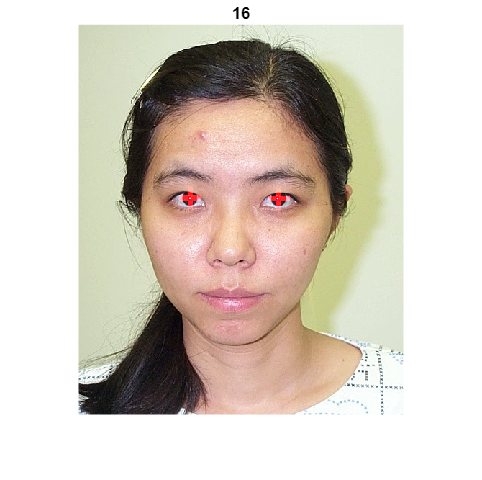

for i =1:16 
    im = im2double(imread("Faces/db1_" + i + ".jpg"));

    [eye1,eye2] = findEyes(im);
    
    imX = drawX(im,eye1(1),eye1(2));
    imX = drawX(imX,eye2(1),eye2(2));
    imshow(imX);title(i)
end